layers = [imageInputLayer([224 224 3]);
          convolution2dLayer(3,16,'Stride',1,'Padding',1);
          batchNormalizationLayer;
          reluLayer();
          maxPooling2dLayer(2,'Stride',2);
          convolution2dLayer(3,32,'Stride',1,'Padding',1);
          batchNormalizationLayer;
          reluLayer();
          maxPooling2dLayer(2,'Stride',2);
          convolution2dLayer(3,64,'Stride',1,'Padding',1);
          batchNormalizationLayer;
          reluLayer();
          fullyConnectedLayer(3);
          softmaxLayer();
          classificationLayer()];

analyzeNetwork(layers)

cnet = layers;
lgraph = layerGraph(cnet);
disp(['Number of Layers: ',num2str(numel(lgraph.Layers))])

Number of Layers: 15


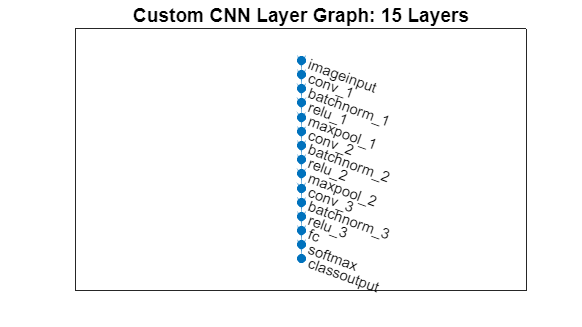

numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['Custom CNN Layer Graph: ',num2str(numberOfLayers),' Layers']);

parentDir = './';
dataDir = 'data';

allImages = imageDatastore(fullfile(parentDir,dataDir),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 130


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 32


options = trainingOptions("adam", ...
    'MiniBatchSize',15,...
    'MaxEpochs',7,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       20.00% |       59.38% |       1.6274 |       3.9187 |      1.0000e-04 |
|       2 |          10 |       00:00:08 |       86.67% |       75.00% |       0.5398 |       0.9712 |      1.0000e-04 |
|       3 |          20 |       00:00:14 |       86.67% |       71.88% |       0.4776 |       0.7777 |      1.0000e-04 |
|       4 |          30 |       00:00:19 |       93.33% |       81.25% |       0.1873 |       0.7318 |      1.0000

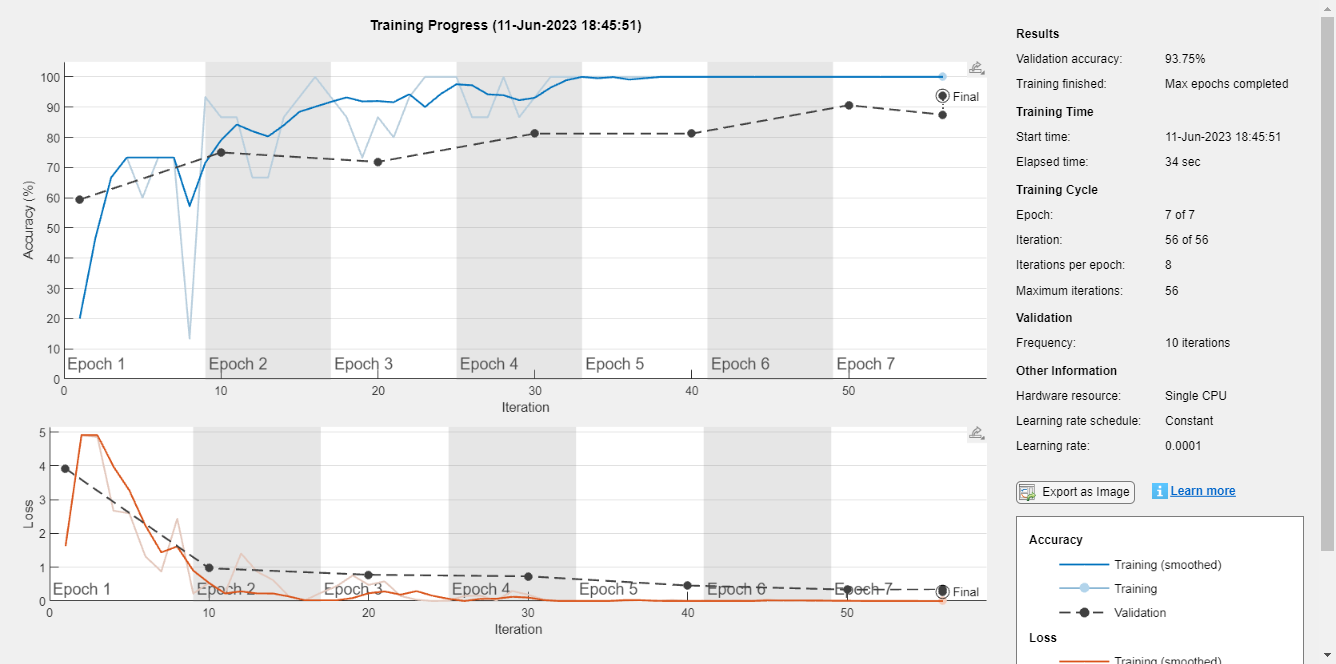

trained_a = trainNetwork(imgsTrain,layers,options);

[YPred_a,probs_a] = classify(trained_a,imgsValidation);
accuracy_a = mean(YPred_a==imgsValidation.Labels);
disp(['Accuracy using adam: ',num2str(100*accuracy_a),'%'])

Accuracy using adam: 93.75%


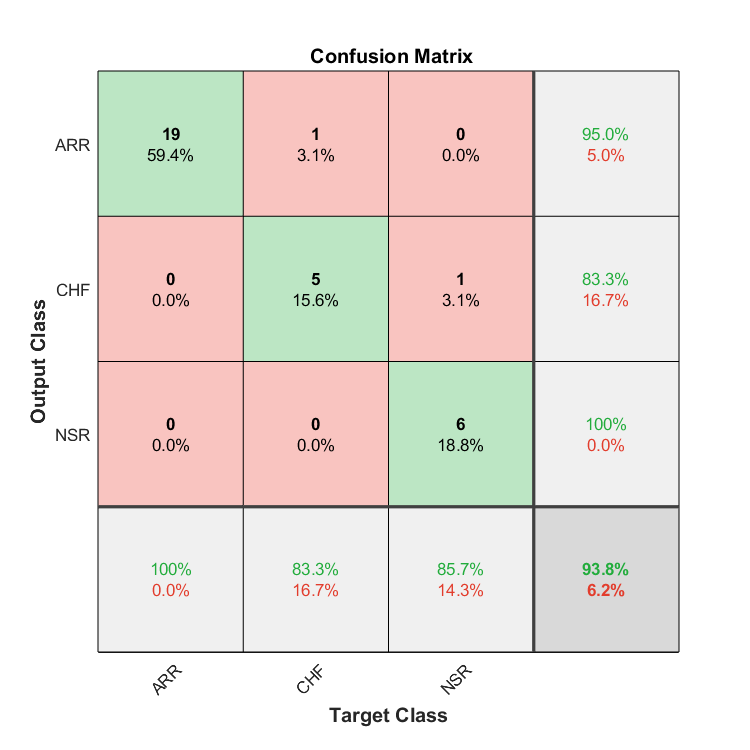

plotconfusion(imgsValidation.Labels,YPred_a)

cm_a = confusionmat(imgsValidation.Labels,YPred_a)

cm_a =     19     0     0
     1     5     0
     0     1     6


cmt_a = cm_a';
diagonal_a = diag(cmt_a);

sum_r = sum(cmt_a,2);
precision_a = diagonal_a./sum_r;
overall_precision_a = mean(precision_a)

overall_precision_a = 0.9278

sum_c = sum(cmt_a,1);
recall_a = diagonal_a./sum_c';
overall_recall_a = mean(recall_a)

overall_recall_a = 0.8968

f1_score_a = (2*overall_precision_a*overall_recall_a)/(overall_recall_a + overall_precision_a)

f1_score_a = 0.9120

a_p = [accuracy_a*100 overall_precision_a*100 overall_recall_a*100 f1_score_a*100]

a_p =    93.7500   92.7778   89.6825   91.2039


x = categorical({'accuracy','precision','recall','f1score'});
x = reordercats(x,{'accuracy','precision','recall','f1score'})
b = bar(x, [a_g;a_s;a_p]')

Error using bar
Data inputs must match the axis configuration. A numeric axis must have numeric data inputs or data inputs which can be converted to double.

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(b(2).YData);
text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(b(3).YData);
text(xtips3,ytips3,labels3,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
legend('GoogleNet','Squeezenet','Custom CNN')
hold off

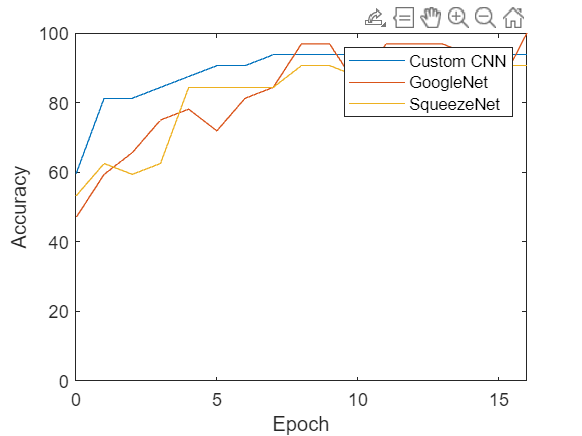

train_x = 0:16;
train_a7y = [59.38 81.25 81.25 84.38 87.50 90.62 90.62 accuracy_a*100 accuracy_a*100 accuracy_a*100 accuracy_a*100 accuracy_a*100 accuracy_a*100 accuracy_a*100 accuracy_a*100 accuracy_a*100 accuracy_a*100];
plot(train_x,train_a7y)
hold on
plot(train_x,train_gy)
hold on
plot(train_x,train_s1y)
xlabel('Epoch')
ylabel('Accuracy')
xlim([0 16])
ylim([0 100])
legend('Custom CNN','GoogleNet','SqueezeNet')
hold off